# Taller XII

### 26/06/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 11 y 12*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

### Unos comentarios frente a los problemas de valor en la frontera

Los problemas de valor en la frontera son ecuaciones diferenciales, normalmente estas condiciones se ven en cuando se presentan derivadas parciales, y son ecuaciones donde solo se especifica las condiciones del contorno de la forma a hallar, se conocen como condiciones tipo *Dirichlet*

Para afrontar estos problemas, la estrategia que adoptaremos es reescribir el problema de frontera en problemas de valores iniciales, con pendientes adecuadas

#### PVF: Transformación a PVI equivalente

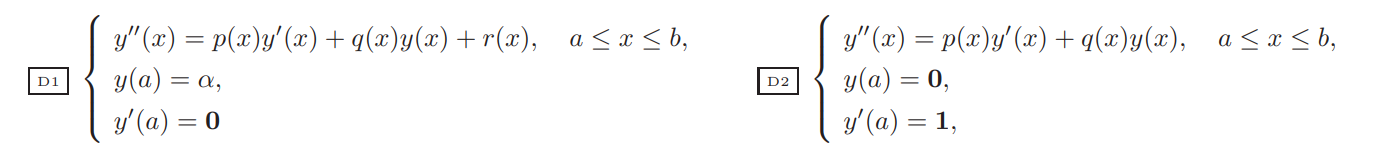

La solución hallada en D1, la notamos como $u\left(x\right)$ y D2 como $v\left(x\right)$, y la consideración de la solución:

`Nota: ``En ingenieria es común afrontar estos problemas de cualquier orden haciendo uso de los métodos de diferencias finitas.`

### Solución númerica de ecuaciones diferenciales ordinarias

Para el taller de esta semana se solucionan dos ejercicios: $\left.\left.\left.\left.\left.1\right),\;2\right),\;4\right),\;6\right)\;\&\;7\right)$ del taller 13

**1. **Considere el problema con valores en la frontera


$$\begin{array}{l}
s\left(x\right)\;{y^{\prime } }^{\prime } \left(x\right)+4\;x\;y^{\prime } \left(x\right)-3x^2 \;y\left(x\right)=-\frac{1}{3}\;\log \left(x\right):2<x<3\\
y\left(2\right)=\frac{3}{2},y\left(3\right)=6\frac{1}{5}\\
y\left(a\right)=\alpha \;,y\left(b\right)=\beta 
\end{array}$$


donde $s\left(x\right)$ es una función continua estrictamente positiva en el intervalo $\left\lbrack 2,3\right\rbrack$.

**    a)** Demuestre que este PVF tiene única solución.

**    b)** Plantee los dos problemas de valor inicial (PVI’s) asociados necesarios para aproximar la solución por el método del disparo; emplee las variables$u\left(x\right)$ y $v\left(x\right)$ para dichos problemas.

**    c)** Las aproximaciones a las soluciones de los PVI’s planteados en el item anterior al emplear el método clásico de Runge-Kutta de orden 4 con tamaño de paso $h=\frac{1}{5}$ son:

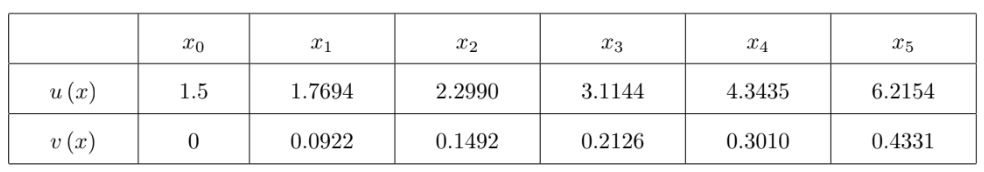

Halle la aproximación a la solución del PVF con el mismo tamaño de paso.

clear

u = [1.5 1.7694 2.2990 3.1144 4.3435 6.2154]; % Solución de D1
v = [0 .0922 .1492 .2126 .3010 .4331]; % Solución de D2

y = u + ( 6.2 - u(end) ) / v(end) * v % Solución de PVF

**2. **Considere el PVF


$$\begin{array}{l}
{y^{\prime } }^{\prime } \left(x\right)\;-\frac{y^{\prime } \left(x\right)}{x}\;-\;3\;\frac{y\left(x\right)}{x^2 }\;-\frac{\log \left(x\right)}{x}=-1:1\le x\le 2\\
y\left(1\right)=0,\;y\left(2\right)=0
\end{array}$$


**a) **¿Tiene el problema de valores en la frontera solución única?

**b) **Enuncie los dos PVI’s que se deben resolver para utilizar el método del disparo lineal.

**c) **Aproxime la solución del PVF con tamaño de paso $h=\frac{1}{3}$. Aplique el método de Euler para resolver cada uno de los PVI’s.

**d)** Utilice` linsht.m` para resolver el PVF con** M = 20.**

**e) **Utilice `findiff.m` para resolver el PVF con **N = 20.**

**f )** Grafique los resultados obtenidos en los tres literales anteriores.

`Solución`

**a) **Verifiquemos las condiciones:

Ecuación a analizar: ${y^{\prime } }^{\prime } \left(x\right)\;=\frac{y^{\prime } \left(x\right)}{x}+\;3\;\frac{y\left(x\right)}{x^2 }+\frac{\log \left(x\right)}{x}-1$ $:1\le x\le 2$

- Coeficientes Continuos

- ¿Es $\frac{1}{x}$ acotable en $1\le x\le 2$ ? : $\frac{1}{x}\le 1$

- ¿Es $\frac{3}{x^2 }>0$? Si

**b) **PVI's

- Primer PVI D1 : $\begin{array}{l}
{y^{\prime } }^{\prime } \left(x\right)\;=\frac{y^{\prime } \left(x\right)}{x}+\;3\;\frac{y\left(x\right)}{x^2 }+\frac{\log \left(x\right)}{x}-1\;:1\le x\le 2\\
y\left(1\right)=0,y^{\prime } \left(2\right)=0
\end{array}$

- Segundo PVI D2 : $\begin{array}{l}
{y^{\prime } }^{\prime } \left(x\right)\;=\frac{y^{\prime } \left(x\right)}{x}+\;3\;\frac{y\left(x\right)}{x^2 }:1\le x\le 2\\
y\left(1\right)=0,y^{\prime } \left(2\right)=1
\end{array}$

**c) **Consideremos:

`Reconstruyamos la función`

Solucionemos el sistema:

clear

F = @(x, Y) [Y(2), Y(2)./x + 3.*Y(1) ./ x.^2 + log(x) ./ x - 1]; % Y = [y, y']
D1 = @(x, Y) F(x, Y);
D2 = @(x, Y) [Y(2), Y(2)./x + 3.*Y(1) ./ x.^2]; % Y = [y, y']


y =     1.5000    1.7661    2.2937    3.1068    4.3328    6.2000


% Auxiliar D1
U = eulers(D1, 1, 2, [0 0], 20);

% Auxiliar D2
V = eulers(D2, 1, 2, [0 1], 20);
u = U(:, 2); % Valores de la función u
v = V(:, 2); % Valores de la función v
y = u + (0 - u(end)) / v(end) * v; % Solución PVI E
E = y;

**d, e) **Consideremos:

help linsht
% Disparo Lineal
LS = linsht(D1, D2, 1, 2, 0, 0, 20);
help findiff
% Diferencias finitas

Ecuación a analizar: ${y^{\prime } }^{\prime } \left(x\right)\;=\frac{y^{\prime } \left(x\right)}{x}+\;3\;\frac{y\left(x\right)}{x^2 }+\frac{\log \left(x\right)}{x}-1$ $:1\le x\le 2$

%  Redefino las funciones:
p = @(x) 1./x;
q = @(x) 3./x.^2;
r = @(x) log(x)./x - 1;

DF = findiff(p, q, r, 1, 2, 0, 0, 20);

**f) **Grafiquemoslas:

T = LS(:, 1);
LS = LS(:, 2);
DF = DF(:, 2);

clf('reset')

  Entrada   - F1 y F2 son los sistemas de ecuaciones de primer orden
              representando los Problemas de Valor Inicial (P.V.I.'s) (9) and (10),
              respectivamente; funciones creadas con @
            - a y b son los extremos del intervalo
            - alpha = x(a)  y  beta = x(b); las condiciones frontera
            - M es el numero de pasos
  Salida    - L = [T', X]; donde  T' es el vector de abscisas (M+1) x 1
              y  X  es el vector de ordenadas  (M+1) x 1



hold on
plot(T, E, 'b', 'DisplayName', 'Aprx. Euler')
plot(T, LS, 'k', 'DisplayName', 'Aprx. Disparo Lineal')

  Entrada - p, q, r  son las funciones coeficientes de
              f(t,x,x')=p(t)x'+q(t)x+r(t)
            introducidas con @
          - a y b son los extremos izquierdo y derecho
          - alpha = x(a)  y  beta = x(b)
          - N es el numero de pasos
  Salida  - F = [T', X']: donde T' es el vector de abscisas  1 x N  y
            X' es el vector de ordenadas  1 x N.



plot(T, DF, 'r', 'DisplayName', 'Aprx. Diferencias finitas')
legend('Location',"south")
grid on
hold off

**4. **Considere el PVF


$$\begin{array}{l}
{y^{\prime } }^{\prime } \left(x\right)=\;2y^{\prime } \left(x\right)+3\;y\left(x\right)\;+\;\cos \left(x\right):0<x<1\\
y\left(0\right)=1,\;y\left(1\right)=0
\end{array}$$


**a) **Utilice `linsht.m` para resolver el PVF con **M = 20**.

**b) **Utilice `findiff.m` para resolver el PVF con** N = 20**.

**c) **Grafique los resultados obtenidos en los dos literales anteriores.

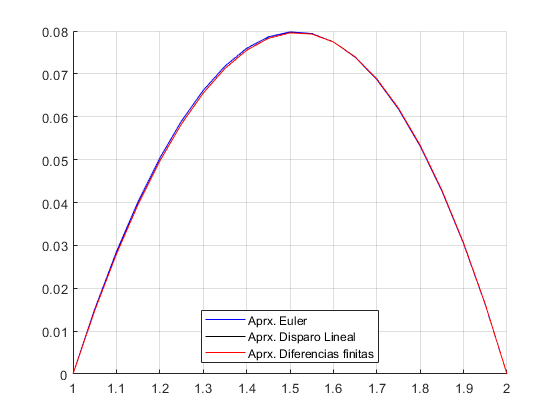

clear

% Disparo lineal
F = @(x, Y) [Y(2), 2*Y(2) + 3*Y(1) + cos(x)]; % Y = [y, y']
D1 = @(x, Y) F(x, Y);
D2 = @(x, Y) [Y(2), 2*Y(2) + 3*Y(1)];
L = linsht(D1, D2, 0, 1, 1, 0, 20);

% Diferencias finitas
D = findiff(@(x) 2.*x.^0, @(x) 3.*x.^0, @(x) cos(x), 0, 1, 1, 0, 20);

T = L(:, 1);
L = L(:, 2);
D = D(:, 2);

clf('reset')
hold on

plot(T, L, 'k', 'DisplayName', 'Aprx. Disparo Lineal')
plot(T, D, 'r', 'DisplayName', 'Aprx. Diferencias finitas')
legend('Location',"south")
grid on
hold off

**6.** Aproxime la solución del PVF


$$\begin{array}{l}
{y^{\prime } }^{\prime } \left(x\right)+\frac{4}{x^2 }\;y^{\prime } \left(x\right)+\frac{2}{x^2 }y\left(x\right)=\frac{2}{x^2 }\;\log \left(x\right):\;1\le x\le 2\\
y\left(1\right)=\frac{1}{2},y\left(2\right)=\log \left(2\right)
\end{array}$$


por medio de disparo lineal y también por el método de diferencias finitas. Grafique sus resultados.

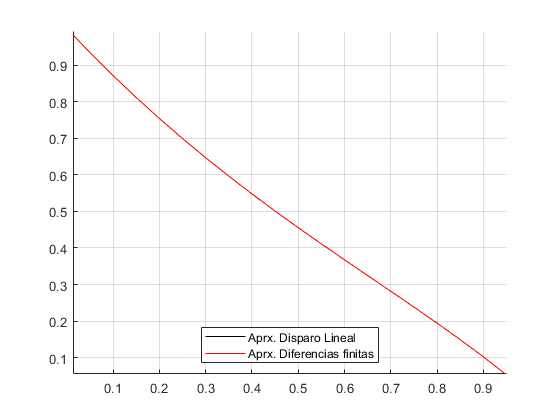

clear

% Definimos las funciones:
F = @(x, Y) [Y(2), (-4 .* Y(2) - 2 .* Y(1) + 2 .* log(x)) ./ x.^2]; % Y = [y, y']
D1 = @(x, Y) F(x, Y);
D2 = @(x, Y)  [Y(2), (-4 .* Y(2) - 2 .* Y(1)) ./ x.^2]; % Y = [y, y']
    
p = @(x) - 4 ./ x.^2;
q = @(x) -2 ./ x.^2;
r = @(x) 2 * log(x) ./ x.^2;

% Definir los métodos
M = 100;

L = linsht(D1, D2, 1, 2, 1/2, log(2), M);
D = findiff(p, q, r, 1, 2, 1/2, log(2), M);

T = L(:, 1);
L = L(:, 2);
D = D(:, 2);

clf('reset')

hold on
plot(T, L, 'k', 'DisplayName', 'Aprx. Disparo Lineal')
plot(T, D, 'r', 'DisplayName', 'Aprx. Diferencias finitas')
legend('Location',"south")
grid on
hold off

**7. **Representamos con $U$ el potencial electrostático entre dos esferas metálicas concéntricas de radios $R_1$ y $R_2$ ($R_1 <R_2$). El potencial de la región situada entre ambas esferas está regido por la ecuación


$$\begin{array}{l}
\frac{d^2 U}{{\textrm{dr}}^2 }\;+\frac{2}{r}\;\frac{\textrm{dU}}{\textrm{dr}}\;=\;0:R_1 \le r\le R_2 \\
U\left(R_1 \right)=V_1 ,\;U\left(R_2 \right)=0
\end{array}$$


suponga que $R_1 =2"$, $R_2 =4"$ y que $V_1 =110\;V$

**a) **Aproxime y grafique el potencial electrostático en intervalos de $\ldotp 05"$. usando el método de disparo lineal.

**b)** Compare los resultados obtenidos con el potencial real


$$U\left(r\right)=\frac{V_1 \;R_1 }{r}\left(\frac{R_2 -r}{R_2 -R_1 }\right)$$


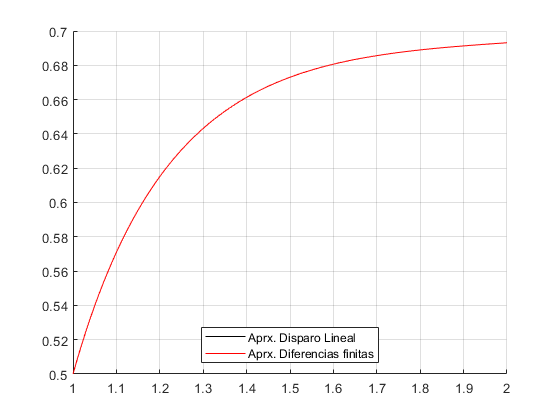

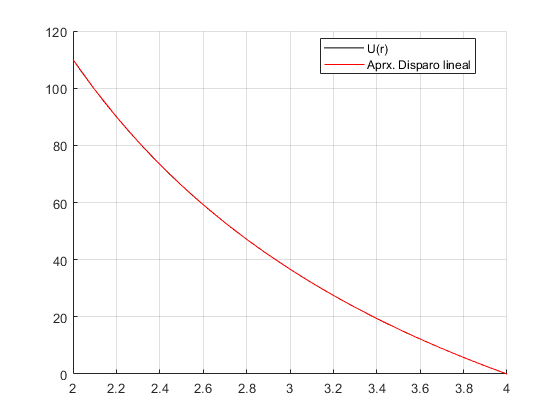

Error = 6.3355e-09

clear

F = @(r, U) [U(2), - 2./r .* U(2)]; % D1 == D2

L = linsht(F, F, 2, 4, 110, 0, 20);
V = 110; R1 = 2; R2 = 4;
U = @(r) V .* R1 ./ r .* (R2 - r) ./ (R2 - R1);

clf('reset')
hold on
fplot(U, [2, 4], 'k', 'DisplayName', 'U(r)')
plot(L(:, 1), L(:, 2), 'r', 'DisplayName', 'Aprx. Disparo lineal')
legend('Location', 'best')
grid on
hold off
r = L(:, 1);
L = L(:, 2);

Error = norm(U(r) - L)^2